# LAB3 MATLAB Programming

涂峻绫(12213010) and 欧阳安男(12211831)

## Introduction

MATLAB is a powerful

## Results and Analysis

### 3.8

#### (a)

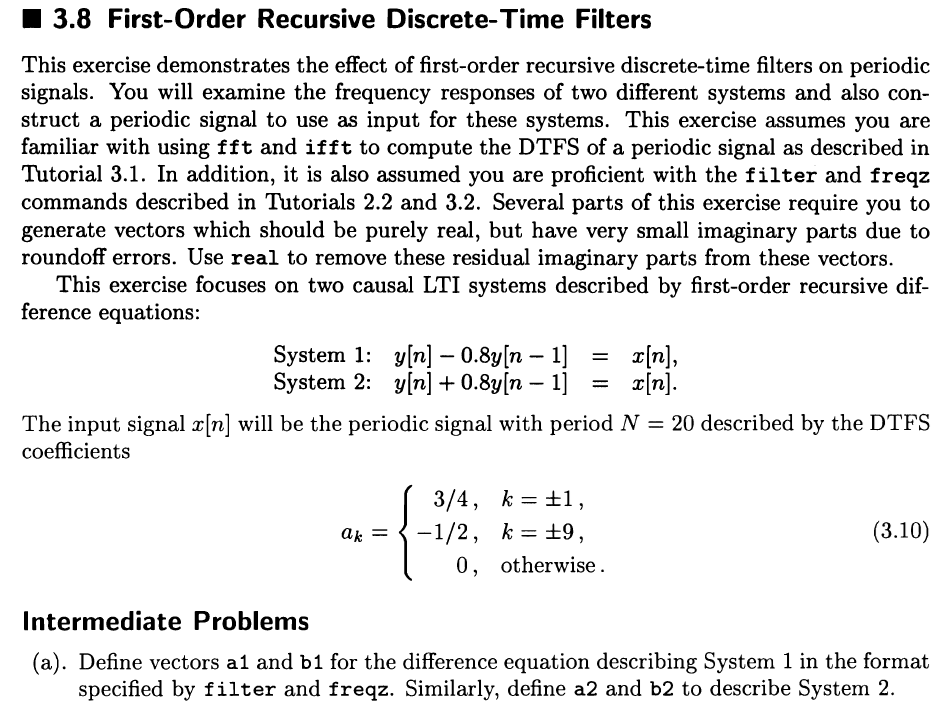

Initialize.

clear; clc; close all;

Create vectors $a_1,b_1$ and $a_2,b_2$.

a1 = [1 -0.8]

a1 =     1.0000   -0.8000


b1 = 1

b1 = 1

a2 = [1 0.8]

a2 =     1.0000    0.8000


b2 = 1

b2 = 1

#### (b)

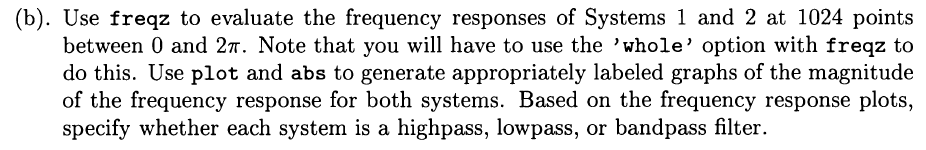

Calculate $H_1,\omega_1,H_2,\omega_2$.

[H1,omega1] = freqz(b1,a1,1024,'whole');
[H2,omega2] = freqz(b2,a2,1024,'whole');

Plot frequency responese for both systems.

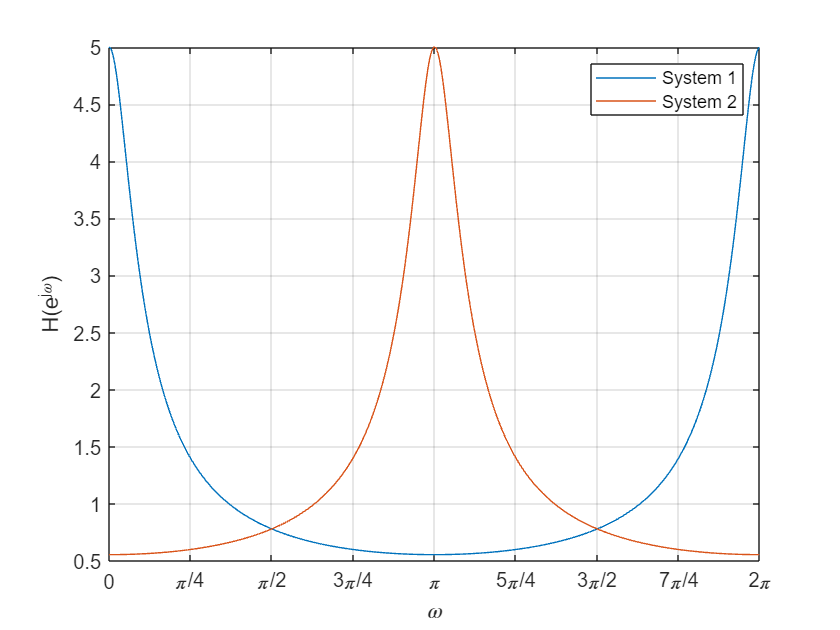

figure;
plot(omega1,abs(H1));
hold on;
plot(omega2,abs(H2));
grid on;
axis([0 2*pi ylim]);
xlabel('\omega');
ylabel('H(e^{j\omega})');
xticks(0:pi/4:2*pi);
xticklabels({'0' '\pi/4' '\pi/2' '3\pi/4' '\pi' '5\pi/4' '3\pi/2' '7\pi/4' '2\pi'});
legend('System 1','System 2');

The frequency responese for system 1 is high when $\omega$ is small and big so system 1 is both highpass and lowpass filter.

The frequency responese for system 2 is high when $\omega$ close to $\pi$ so system 2 is bandpass filter.

#### (e)

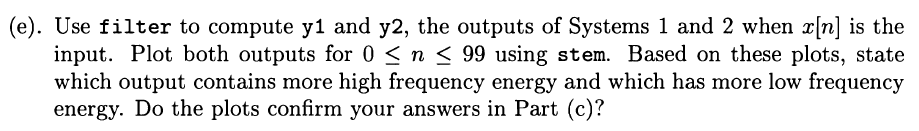

### 3.10

#### (a)

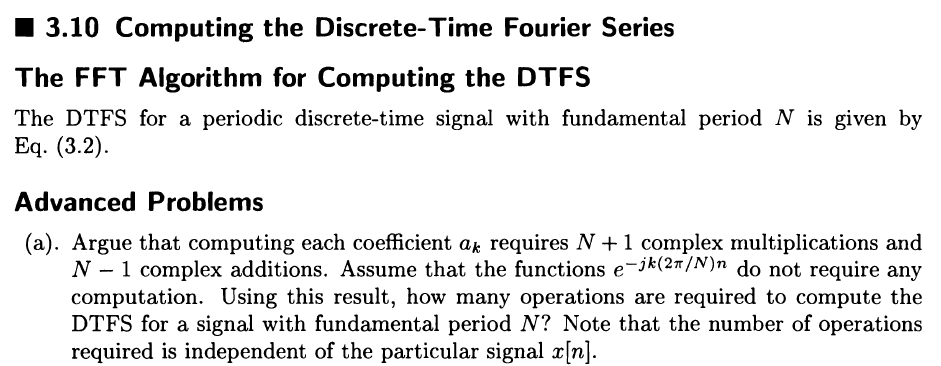

clear; clc; close all;

Need $N(N+1)$ complex multiplications and $N(N-1)$ complex additions.

#### (b)

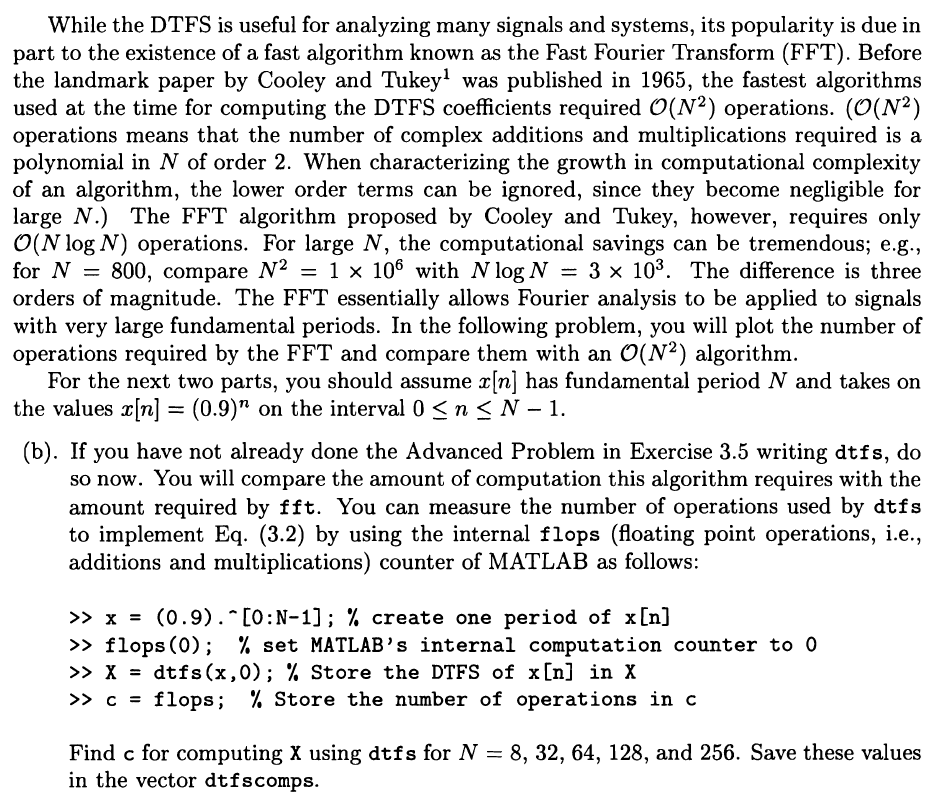

Since flops has been removed so use the execution time to be the substitude.

N_list = [8 32 64 128 256];
dtfscomps = zeros(1,length(N_list));
for i = 1:5
    N = N_list(i);
    x = (0.9).^(0:N-1);
    tic;
    dtfs(x,0);
    dtfscomps(i) = toc;
end

#### (c)

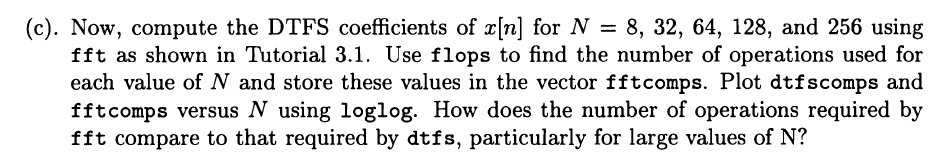

Since flops has been removed so use the execution time to be the substitude.

fftcomps = zeros(1,length(N_list));
for i = 1:5
    N = N_list(i);
    x = (0.9).^(0:N-1);
    tic;
    fft(x,0);
    fftcomps(i) = toc;
end

Plot $dtfscomps$ and $fftcomps$.

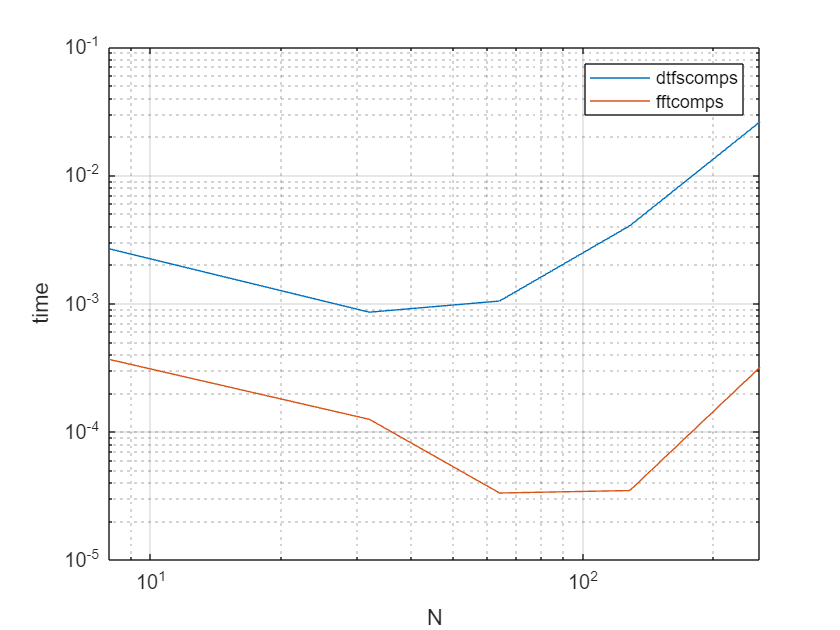

figure;
loglog(N_list,dtfscomps);
hold on;
loglog(N_list,fftcomps);
grid on;
xlabel('N');
ylabel('time');
legend('dtfscomps','fftcomps');

According to the figure, the cost time of $dtfs$ increases obviously while $fft$ increases too slowly to be observed.

#### (d)

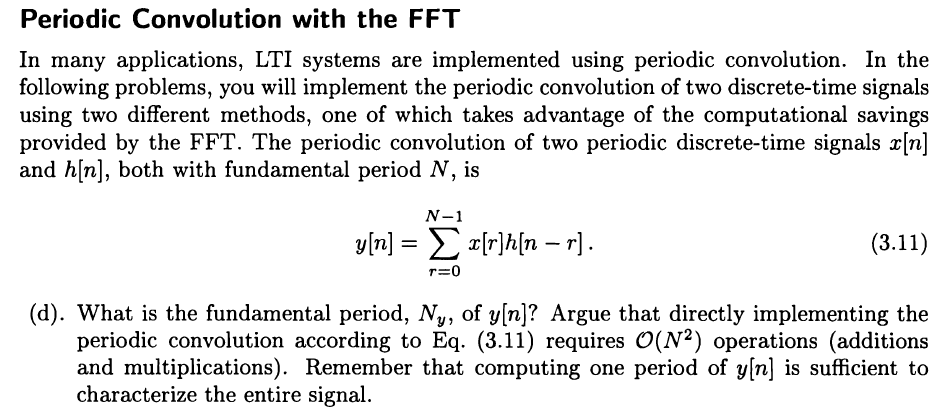

Because $h[n]$ has a fundamental period N, $h[n+N-r]=h[n-r]$.

So $y[n]=\sum_{r=0}^{N-1}x[r]h[n-r]=\sum_{r=0}^{N-1}x[r]h[n+N-r]=y[n+N]$, $N_y=N$.

#### (e)

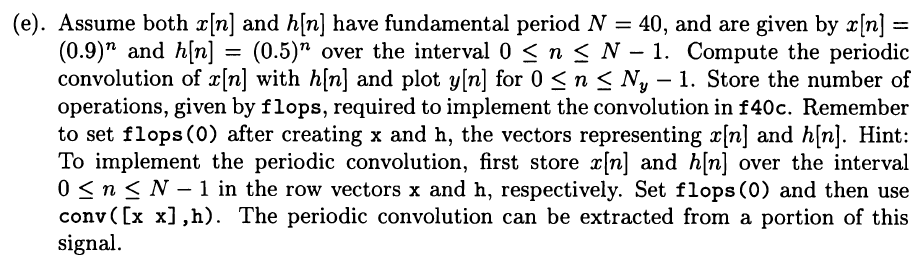

Initialize $N,x[n],h[n]$.

N = 40;
x = 0.9.^(0:(N-1));
h = 0.5.^(0:(N-1));

Calculate $N_y,y[n],f40c$.

Ny = N;
tic;
y = conv([x x],h);
y = y(1:Ny);
f40c = toc;

Plot $y[n]$.

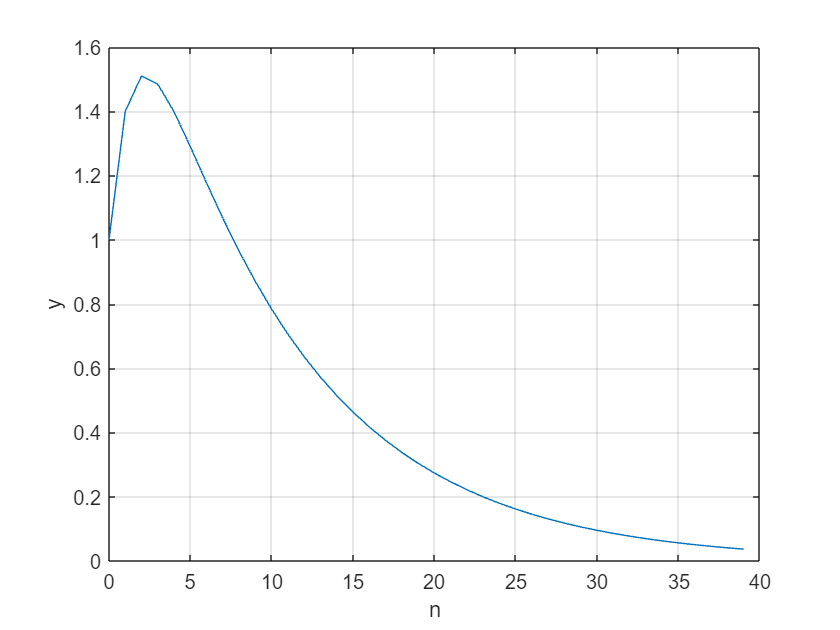

figure;
plot(0:(Ny-1),y);
grid on;
xlabel('n');
ylabel('y');

#### (f)

Initialize $N,x[n],h[n]$.

N = 80;
x = 0.9.^(0:(N-1));
h = 0.5.^(0:(N-1));

Calculate $N_y,y[n],f80c$.

Ny = N;
tic;
y = conv([x x],h);
y = y(1:Ny);
f80c = toc;

Plot $y[n]$.

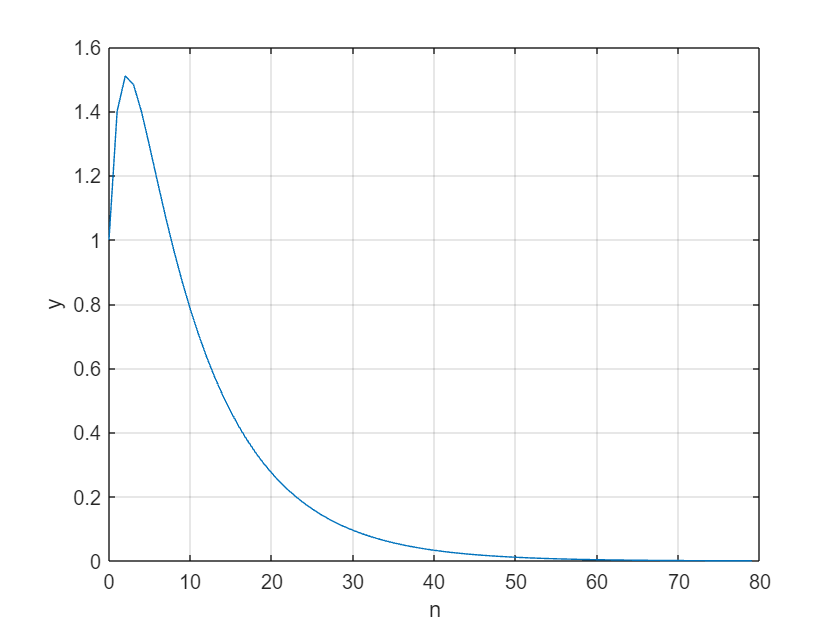

figure;
plot(0:(Ny-1),y);
grid on;
xlabel('n');
ylabel('y');

#### (g)

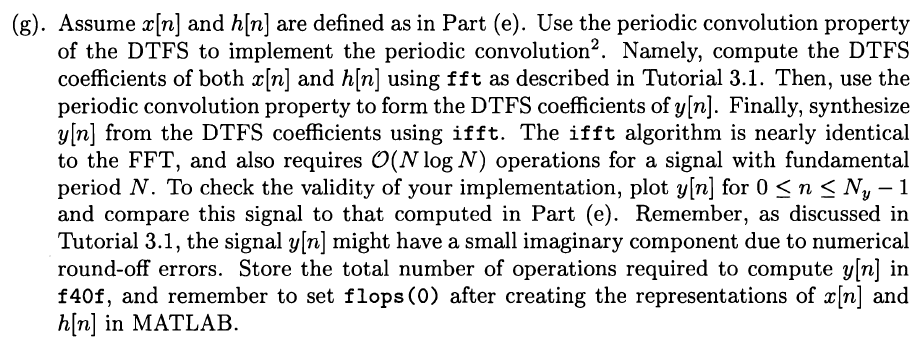

Initialize $N,x[n],h[n]$.

N = 40;
x = 0.9.^(0:(N-1));
h = 0.5.^(0:(N-1));

Calculate $N_y,y[n],f40f$.

Ny = N;
tic;
DTFSx = fft(x);
DTFSh = fft(h);
DTFSy = DTFSx.*DTFSh;
y = ifft(DTFSy);
f40f = toc;

Plot $y[n]$.

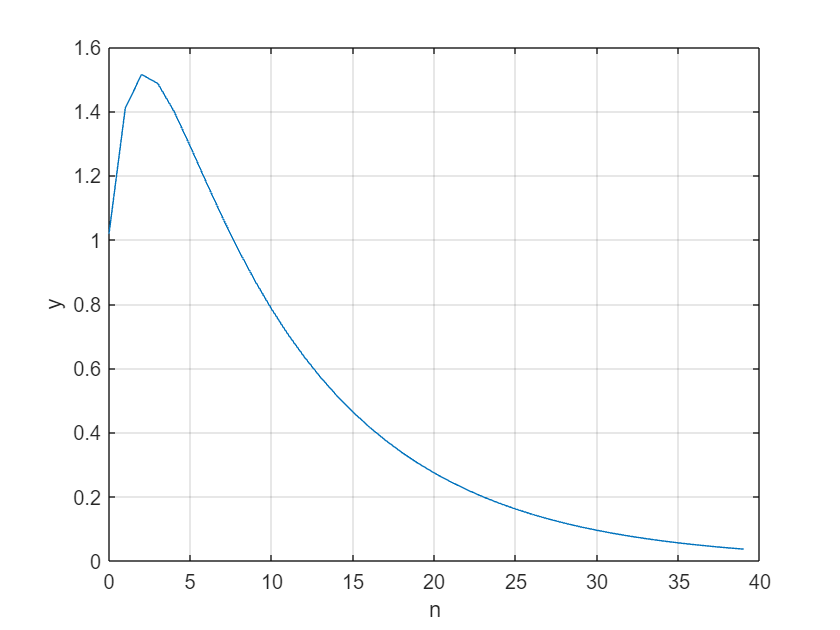

figure;
plot(0:(Ny-1),y);
grid on;
xlabel('n');
ylabel('y');

#### (h)

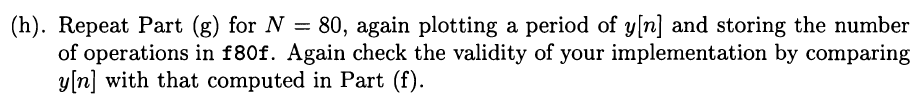

Initialize $N,x[n],h[n]$.

N = 80;
x = 0.9.^(0:(N-1));
h = 0.5.^(0:(N-1));

Calculate $N_y,y[n],f80f$.

Ny = N;
tic;
DTFSx = fft(x);
DTFSh = fft(h);
DTFSy = DTFSx.*DTFSh;
y = ifft(DTFSy);
f80f = toc;

Plot $y[n]$.

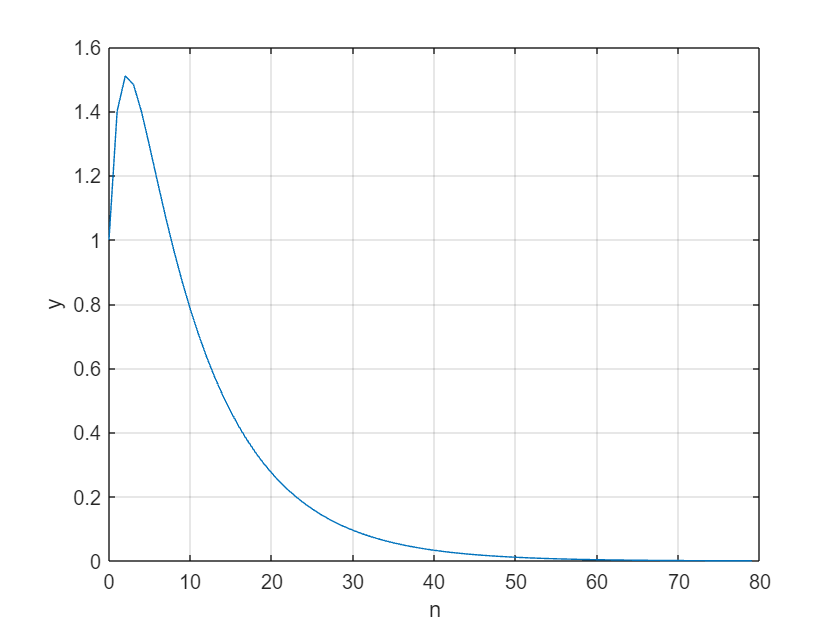

figure;
plot(0:(Ny-1),y);
grid on;
xlabel('n');
ylabel('y');

#### (i)

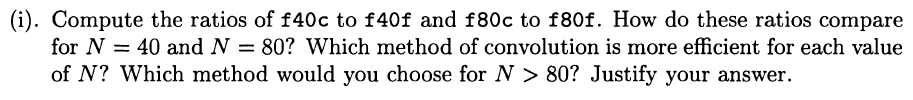

Compute the ratios of $\frac{f40c}{f40f}$ and $\frac{f80c}{f80f}$.

ratio40 = f40c/f40f

ratio40 = 0.9541

ratio80 = f80c/f80f

ratio80 = 0.4755

Convolution directly are more efficient in both  $N=40$ and $N=80$. The ratio is also decreasing as $N$ increases. But it's because the data size is so small that the time can't reflect the actual efficiency of the algorithm. Cache, instruction pipeline, matlab's optimization when data size increasing, etc. Many factors influence the time. So we can't figure out which is more efficient until the data size is large enough to make the calculate time takes the main parts of the whole time. But theoretically time complexity of the first method is $O(n^2)$ while the second is $O(nlogn)$. So I would use fft and ifft when $N>80$.

Test the time when $N=1e6$.

N = 10^6;
x = 0.9.^(0:(N-1));
h = 0.5.^(0:(N-1));
Ny = N;
tic;
y = conv([x x],h);
y = y(1:Ny);
f1e6c = toc;
tic;
DTFSx = fft(x);
DTFSh = fft(h);
DTFSy = DTFSx.*DTFSh;
y = ifft(DTFSy);
f1e6f = toc;
f1e6c, f1e6f

f1e6c = 1.2504

f1e6f = 0.0468

### Functions

Unit step function

function a = dtfs(x,n_init)
    m = zeros(length(x),length(x));
    for i = 1:length(x)
        for j = 1:length(x)
            m(j,i) = exp(-1i*2*pi/length(x)*(i-1)*(j+n_init-1))/length(x);
        end
    end
    a = x*m;
end

## Expeience

........................